clear; clc; close all;
rng(0);

%% --- PARAMETRI ---
tol = 1e-4; maxit = 1000; energy_threshold = 0.95;
epochs = 50; learning_rate = 0.01; bottleneck = 40;
train_ratio = 0.8;

%% --- SETUP PATH ---
projectRoot = pwd;
addpath(genpath(projectRoot));
this_folder = pwd;
results_path = fullfile(this_folder,'results');
if ~exist(results_path,'dir'), mkdir(results_path); end

%% --- CARICAMENTO DATI E PREPROCESSING ---
load('dataset/volti_dataset.mat');  % A (m×n)
A = double(A)/255;
[m, n] = size(A); img_h = 112; img_w = 92;

mean_face = mean(A,2);
A_centered = A - mean_face;

%% --- SVD_BC ---
[U, S, V] = svd_BC(A_centered, tol, maxit);

   [svd_BC] costruisco ATA...
   [svd_BC] chiamo qr_eig su 410x410 (tol=1.0e-04,maxit=1000)...
         [qr_eig] deflazione k=410 ... 

iter=1001 time=13.16 s
         [qr_eig] deflazione k=409 ... 

iter=1001 time=14.18 s
         [qr_eig] deflazione k=408 ... 

iter=1001 time=12.70 s
         [qr_eig] deflazione k=407 ... 

iter=1001 time=13.32 s
         [qr_eig] deflazione k=406 ... 

iter=1001 time=14.40 s
         [qr_eig] deflazione k=405 ... 

iter=1001 time=11.13 s
         [qr_eig] deflazione k=404 ... iter=611 time=7.13 s
         [qr_eig] deflazione k=403 ... 

iter=1001 time=12.16 s
         [qr_eig] deflazione k=402 ... 

iter=1001 time=12.41 s
         [qr_eig] deflazione k=401 ... 

iter=1001 time=11.70 s
         [qr_eig] deflazione k=400 ... 

iter=1001 time=14.14 s
         [qr_eig] deflazione k=399 ... 

iter=1001 time=12.40 s
         [qr_eig] deflazione k=398 ... 

iter=1001 time=10.98 s
         [qr_eig] deflazione k=397 ... 

iter=1001 time=10.70 s
         [qr_eig] deflazione k=396 ... 

iter=1001 time=12.59 s
         [qr_eig] deflazione k=395 ... 

iter=1001 time=13.13 s
         [qr_eig] deflazione k=394 ... 

iter=1001 time=10.27 s
         [qr_eig] deflazione k=393 ... 

iter=1001 time=10.40 s
         [qr_eig] deflazione k=392 ... 

iter=1001 time=10.05 s
         [qr_eig] deflazione k=391 ... 

iter=1001 time=10.09 s
         [qr_eig] deflazione k=390 ... 

iter=1001 time=10.47 s
         [qr_eig] deflazione k=389 ... 

iter=1001 time=10.46 s
         [qr_eig] deflazione k=388 ... 

iter=1001 time=10.50 s
         [qr_eig] deflazione k=387 ... 

iter=1001 time=10.46 s
         [qr_eig] deflazione k=386 ... iter=407 time=4.10 s
         [qr_eig] deflazione k=385 ... 

iter=1001 time=10.03 s
         [qr_eig] deflazione k=384 ... 

iter=1001 time=9.81 s
         [qr_eig] deflazione k=383 ... 

iter=1001 time=10.30 s
         [qr_eig] deflazione k=382 ... 

iter=1001 time=10.07 s
         [qr_eig] deflazione k=381 ... 

iter=1001 time=9.70 s
         [qr_eig] deflazione k=380 ... 

iter=1001 time=10.91 s
         [qr_eig] deflazione k=379 ... 

iter=1001 time=9.87 s
         [qr_eig] deflazione k=378 ... iter=136 time=1.23 s
         [qr_eig] deflazione k=377 ... 

iter=1001 time=10.21 s
         [qr_eig] deflazione k=376 ... 

iter=1001 time=9.70 s
         [qr_eig] deflazione k=375 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=374 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=373 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=372 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=371 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=370 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=369 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=368 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=367 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=366 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=365 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=364 ... 

iter=1001 time=9.62 s
         [qr_eig] deflazione k=363 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=362 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=361 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=360 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=359 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=358 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=357 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=356 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=355 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=354 ... iter=478 time=4.24 s
         [qr_eig] deflazione k=353 ... 

iter=1001 time=9.60 s
         [qr_eig] deflazione k=352 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=351 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=350 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=349 ... 

iter=1001 time=8.96 s
         [qr_eig] deflazione k=348 ... 

iter=1001 time=8.61 s
         [qr_eig] deflazione k=347 ... 

iter=1001 time=9.25 s
         [qr_eig] deflazione k=346 ... 

iter=1001 time=9.38 s
         [qr_eig] deflazione k=345 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=344 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=343 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=342 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=341 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=340 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=339 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=338 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=337 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=336 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=335 ... 

iter=1001 time=8.70 s
         [qr_eig] deflazione k=334 ... 

iter=1001 time=9.89 s
         [qr_eig] deflazione k=333 ... iter=39 time=0.37 s
         [qr_eig] deflazione k=332 ... 

iter=1001 time=8.40 s
         [qr_eig] deflazione k=331 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=330 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=329 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=328 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=327 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=326 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=325 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=324 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=323 ... iter=2 time=0.02 s
         [qr_eig] deflazione k=322 ... 

iter=1001 time=7.66 s
         [qr_eig] deflazione k=321 ... 

iter=1001 time=7.59 s
         [qr_eig] deflazione k=320 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=319 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=318 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=317 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=316 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=315 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=314 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=313 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=312 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=311 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=310 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=309 ... 

iter=1001 time=7.83 s
         [qr_eig] deflazione k=308 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=307 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=306 ... iter=170 time=1.34 s
         [qr_eig] deflazione k=305 ... iter=222 time=1.66 s
         [qr_eig] deflazione k=304 ... iter=901 time=6.54 s
         [qr_eig] deflazione k=303 ... 

iter=1001 time=7.34 s
         [qr_eig] deflazione k=302 ... iter=11 time=0.14 s
         [qr_eig] deflazione k=301 ... 

iter=1001 time=7.44 s
         [qr_eig] deflazione k=300 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=299 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=298 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=297 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=296 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=295 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=294 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=293 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=292 ... iter=326 time=2.16 s
         [qr_eig] deflazione k=291 ... 

iter=1001 time=7.07 s
         [qr_eig] deflazione k=290 ... 

iter=1001 time=6.78 s
         [qr_eig] deflazione k=289 ... 

iter=1001 time=7.42 s
         [qr_eig] deflazione k=288 ... 

iter=1001 time=6.92 s
         [qr_eig] deflazione k=287 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=286 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=285 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=284 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=283 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=282 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=281 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=280 ... 

iter=1001 time=7.67 s
         [qr_eig] deflazione k=279 ... 

iter=1001 time=6.41 s
         [qr_eig] deflazione k=278 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=277 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=276 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=275 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=274 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=273 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=272 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=271 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=270 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=269 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=268 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=267 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=266 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=265 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=264 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=263 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=262 ... iter=0 time

iter=1001 time=6.36 s
         [qr_eig] deflazione k=259 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=258 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=257 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=256 ... 

iter=1001 time=5.60 s
         [qr_eig] deflazione k=255 ... iter=2 time=0.01 s
         [qr_eig] deflazione k=254 ... 

iter=1001 time=5.86 s
         [qr_eig] deflazione k=253 ... iter=312 time=1.92 s
         [qr_eig] deflazione k=252 ... iter=626 time=3.72 s
         [qr_eig] deflazione k=251 ... 

iter=1001 time=6.72 s
         [qr_eig] deflazione k=250 ... 

iter=1001 time=7.54 s
         [qr_eig] deflazione k=249 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=248 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=247 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=246 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=245 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=244 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=243 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=242 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=241 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=240 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=239 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=238 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=237 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=236 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=235 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=234 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=233 ... 

iter=1001 time=7.96 s
         [qr_eig] deflazione k=232 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=231 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=230 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=229 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=228 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=227 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=226 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=225 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=224 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=223 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=222 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=221 ... 

iter=1001 time=4.99 s
         [qr_eig] deflazione k=220 ... 

iter=1001 time=4.95 s
         [qr_eig] deflazione k=219 ... 

iter=1001 time=5.13 s
         [qr_eig] deflazione k=218 ... 

iter=1001 time=4.99 s
         [qr_eig] deflazione k=217 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=216 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=215 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=214 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=213 ... iter=561 time=2.82 s
         [qr_eig] deflazione k=212 ... 

iter=1001 time=4.52 s
         [qr_eig] deflazione k=211 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=210 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=209 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=208 ... 

iter=1001 time=4.66 s
         [qr_eig] deflazione k=207 ... 

iter=1001 time=4.41 s
         [qr_eig] deflazione k=206 ... 

iter=1001 time=4.51 s
         [qr_eig] deflazione k=205 ... 

iter=1001 time=4.49 s
         [qr_eig] deflazione k=204 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=203 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=202 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=201 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=200 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=199 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=198 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=197 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=196 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=195 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=194 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=193 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=192 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=191 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=190 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=189 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=188 ... iter=0 time

iter=1001 time=3.77 s
         [qr_eig] deflazione k=173 ... iter=760 time=2.78 s
         [qr_eig] deflazione k=172 ... 

iter=1001 time=3.80 s
         [qr_eig] deflazione k=171 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=170 ... 

iter=1001 time=4.15 s
         [qr_eig] deflazione k=169 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=168 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=167 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=166 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=165 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=164 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=163 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=162 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=161 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=160 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=159 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=158 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=157 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=156 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=155 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=154 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=153 ... iter=0 time

iter=1001 time=0.24 s
         [qr_eig] deflazione k=50 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=49 ... 

iter=1001 time=0.18 s
         [qr_eig] deflazione k=48 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=47 ... iter=3 time=0.00 s
         [qr_eig] deflazione k=46 ... iter=35 time=0.01 s
         [qr_eig] deflazione k=45 ... 

iter=1001 time=0.16 s
         [qr_eig] deflazione k=44 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=43 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=42 ... 

iter=1001 time=0.15 s
         [qr_eig] deflazione k=41 ... iter=1 time=0.00 s
         [qr_eig] deflazione k=40 ... 

iter=1001 time=0.13 s
         [qr_eig] deflazione k=39 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=38 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=37 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=36 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=35 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=34 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=33 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=32 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=31 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=30 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=29 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=28 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=27 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=26 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=25 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=24 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=23 ... iter=0 time=0.00 s
         

iter=1001 time=0.02 s
         [qr_eig] deflazione k=9 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=8 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=7 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=6 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=5 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=4 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=3 ... iter=0 time=0.00 s
         [qr_eig] deflazione k=2 ... iter=0 time=0.00 s
      [qr_eig] tutti autovalori estratti.
   [svd_BC] qr_eig completata in 661.29 s
   [svd_BC] costruisco S e U...



eigvals = diag(S);
energy = cumsum(eigvals)/sum(eigvals);
k = find(energy>energy_threshold,1);

%% --- PCA & Normalizzazione ---
P = U(:,1:k)' * (A - mean_face); % [k x n]
mu_P = mean(P,2);
sigma_P = std(P,0,2) + eps;
P_norm = (P - mu_P) ./ sigma_P;
X = P_norm'; % [n x k]

%% --- SPLIT TRAIN/TEST ---
idx = randperm(n);
n_train = round(train_ratio * n);
X_train = X(idx(1:n_train), :);
X_test  = X(idx(n_train+1:end), :);

%% --- TRAIN AUTOENCODER ---
[W_enc, b_enc, W_dec, b_dec, loss_history] = ...
    autoencoder_train(X_train, bottleneck, epochs, learning_rate);

[AE] Epoca 10/50, MSE=0.94702
[AE] Epoca 20/50, MSE=0.90360
[AE] Epoca 30/50, MSE=0.83319
[AE] Epoca 40/50, MSE=0.75262
[AE] Epoca 50/50, MSE=0.65669



%% --- EVALUATION: MSE e COSINE ---
% Funzione utili
cosine_sim = @(x,y) dot(x,y) / (norm(x)*norm(y)+eps);

mse = @(X1,X2) mean(sum((X1-X2).^2,2));
cosacc = @(X1,X2,thr) mean(arrayfun(@(i) cosine_sim(X1(i,:)',X2(i,:)')>thr, 1:size(X1,1)));

% --- Ricostruzione train
X_train_rec = zeros(size(X_train));
for i=1:size(X_train,1)
    x = X_train(i,:)';
    h = max(0, W_enc*x + b_enc);
    X_train_rec(i,:) = (W_dec*h + b_dec)';
end
mse_train = mse(X_train, X_train_rec);
cos_train = mean(arrayfun(@(i) cosine_sim(X_train(i,:)', X_train_rec(i,:)'), 1:size(X_train,1)));

% --- Ricostruzione test
X_test_rec = zeros(size(X_test));
for i=1:size(X_test,1)
    x = X_test(i,:)';
    h = max(0, W_enc*x + b_enc);
    X_test_rec(i,:) = (W_dec*h + b_dec)';
end
mse_test = mse(X_test, X_test_rec);
cos_test = mean(arrayfun(@(i) cosine_sim(X_test(i,:)', X_test_rec(i,:)'), 1:size(X_test,1)));

fprintf('>>> Train MSE loss (autoencoder): %.4f\n', mse_train);

>>> Train MSE loss (autoencoder): 257.7994


fprintf('>>> Test  MSE loss (autoencoder): %.4f\n', mse_test);

>>> Test  MSE loss (autoencoder): 275.5215


fprintf('>>> Train mean cosine similarity:  %.4f\n', cos_train);

>>> Train mean cosine similarity:  0.5670


fprintf('>>> Test  mean cosine similarity:  %.4f\n', cos_test);

>>> Test  mean cosine similarity:  0.5419



%% --- Accuracy come % ricostruzioni "buone" (MSE < THR oppure cosine > thr) ---
THR_MSE = 0.05;
acc_train = mean(arrayfun(@(i) mean((X_train(i,:)' - X_train_rec(i,:)').^2) < THR_MSE, 1:size(X_train,1)));
acc_test = mean(arrayfun(@(i) mean((X_test(i,:)'  - X_test_rec(i,:)').^2)  < THR_MSE, 1:size(X_test,1)));

THR_COS = 0.95; % puoi cambiare questa soglia
cos_acc_train = cosacc(X_train, X_train_rec, THR_COS);
cos_acc_test  = cosacc(X_test,  X_test_rec,  THR_COS);

fprintf('>>> Train cosine similarity (cosine > %.2f): %.2f%%\n', THR_COS, 100*cos_acc_train);

>>> Train cosine similarity (cosine > 0.95): 0.00%


fprintf('>>> Test  cosine similarity (cosine > %.2f): %.2f%%\n', THR_COS, 100*cos_acc_test);

>>> Test  cosine similarity (cosine > 0.95): 0.00%


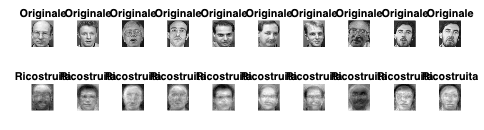


%% --- VISUALIZZAZIONE RICOSTRUZIONI (su test) ---
num_show = 10;
perm = randperm(size(X_test,1), num_show);

% Ricrea U_k per la proiezione inversa
U_k = U(:,1:k);

%% Visualizzazione ricostruzioni
% Scegli alcune immagini a caso dal dataset e confronta
num_show = 10;

figure('Name','Autoencoder + PCA: ricostruzioni (test)','NumberTitle','off', 'Position', [100, 100, 120*num_show, 320]);
tiledlayout(2, num_show, 'Padding','compact', 'TileSpacing','compact');
for i = 1:num_show
    x_pca = X_test(perm(i), :)';
    h     = max(0, W_enc * x_pca + b_enc);
    x_hat = W_dec * h + b_dec;
    orig_idx = idx(n_train+perm(i));
    x_rec = U_k * x_hat + mean_face;

    nexttile(i)
    imshow(reshape(A(:,orig_idx), img_h, img_w), []);
    title('Originale','FontSize',12);

    nexttile(i + num_show)
    imshow(reshape(x_rec, img_h, img_w), []);
    title('Ricostruita','FontSize',12);
end
saveas(gcf, fullfile(results_path,'ae_pca_reconstructions.png'));

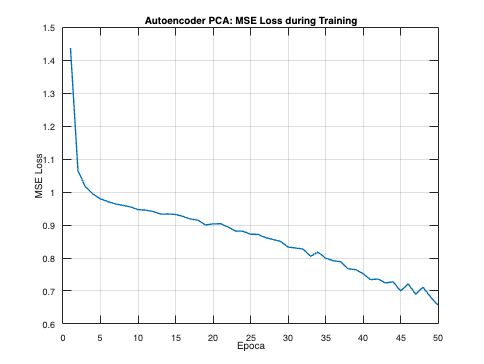


%% --- ANDAMENTO DELLA LOSS ---
figure; plot(1:epochs, loss_history, 'LineWidth',1.5);
xlabel('Epoca'); ylabel('MSE Loss'); title('Autoencoder PCA: MSE Loss during Training');
grid on; saveas(gcf, fullfile(results_path,'ae_pca_loss.png'));